%clearing the workspace environment
clc
clear
close all

%setting up the camera 

%declaring the webcam to camera
camera = webcam;
%camera will start after this command

%clicking the snapshot using the camera
picture = camera.snapshot;

%clearing the camera
clear camera;
%camera will stop after this command

%initilising the pre trained network and then using the transfer learning
%to just modify the network to our own needs
net = googlenet;

%taking the size of the first layer so that we can preprocess our image
%accourding to our needs
inlayer = net.Layers(1)

inlayer =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]
        SplitComplexInputs: 0

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224x224x3 single]


%storing the input size and displaying it in a variable
expectedSize = inlayer.InputSize

expectedSize =    224   224     3


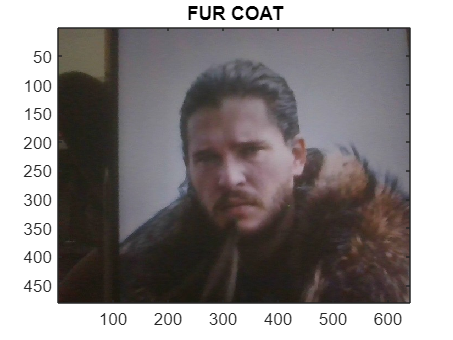

%pre prossing the live data taken from the camera
figure(1);
image(picture);

%resizing the picture so that it can be used for the network
picture = imresize(picture,[224,224]);

%classifying the image taken from the camera
label = classify(net, picture);

%naming the title by the name of classified class 
title(upper(char(label)));